Hvor N betyder normal fordelt

hvor n er antallet af data punkter i en stikprøve


$$\bar Y :N(\mu, \frac{\sigma^2}{n})$$


clear
stik = 1000;  % antal stikprøver
n = 1000; %antal data der tages middel værdi af (kvaliteten af stikprøven)

for i = 1:stik
    for j = 1:n 
    Y(j) = randi(6,1);
    end
    Ms(i) = mean(Y);
end
SEM = std(Ms) /  sqrt(n) %var(Ms) %Standard Error of the Mean

SEM = 0.0017

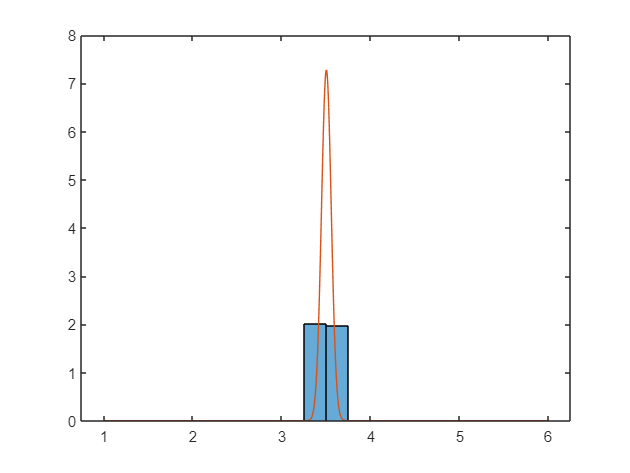

histogram(Ms,1:0.25:6, "Normalization","pdf")
hold on
dist = makedist("Normal", "mu",mean(Ms), "sigma",std(Ms));
x = linspace(1,6,stik);
df = pdf(dist, x);
plot(x,df)
hold off

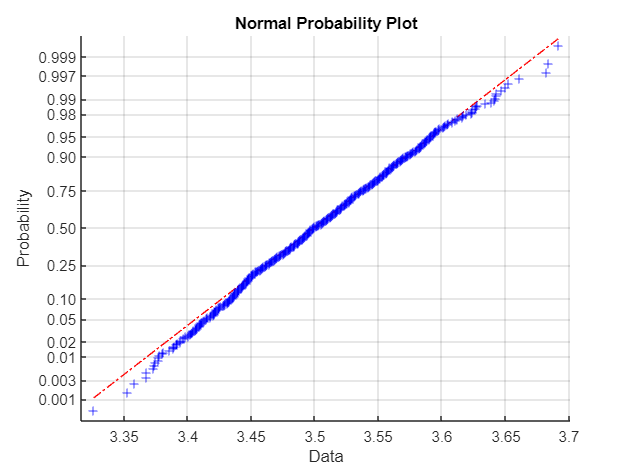

normplot(Ms)